## Section 1: LHS Sampling

이 섹션은 차량 서스펜션의 앞/뒤 스프링 강성(k)과 감쇠 계수(c)에 대해, 가능한 설계 변수 조합을 효율적으로 샘플링하기 위한 **라틴 하이퍼큐브 샘플링(Latin Hypercube Sampling, LHS)** 을 수행하는 단계입니다.

LHS는 무작위성은 유지하되, 각 변수의 분포 범위를 고르게 커버하면서 변수 간 상관관계를 최소화하여 정교한 설계 공간 탐색을 가능하게 합니다. 샘플링된 값들은 이후 동역학 해석에서 동일한 조건으로 사용됩니다.

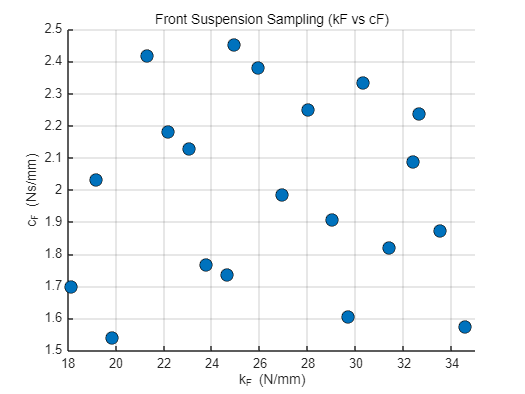

%% LHS Sampling of Suspension Parameters
% 서스펜션의 전/후륜 강성(k) 및 감쇠계수(c)에 대해
% 상관관계를 최소화한 라틴 하이퍼큐브 샘플링 수행
% 단위: k (N/mm), c (Ns/mm)

% 설정
n_samples = 20;
n_iter = 10000;
k_min = 18; k_max = 35;
c_min = 1.5; c_max = 2.5;
n_vars = 4;

% LHS 최적화
best_corr = inf;
for i = 1:n_iter
    lhs_unit = lhsdesign(n_samples, n_vars, 'criterion', 'maximin', 'iterations', 5);
    kF = k_min + (k_max - k_min) * lhs_unit(:,1);
    cF = c_min + (c_max - c_min) * lhs_unit(:,2);
    kR = k_min + (k_max - k_min) * lhs_unit(:,3);
    cR = c_min + (c_max - c_min) * lhs_unit(:,4);
    sample_scaled = [kF, cF, kR, cR];

    R = corrcoef(sample_scaled);
    corr_sum = sum(sum(abs(R - eye(n_vars))));

    if corr_sum < best_corr
        best_corr = corr_sum;
        best_sample = sample_scaled;
    end
end

% 유효성 확인
if ~exist('best_sample', 'var') || isempty(best_sample)
    error('LHS sampling failed. No valid sample found.');
end

% 단위 변환 및 구조체 생성 (N/mm → N/m, Ns/mm → Ns/m)
params = struct();
for i = 1:n_samples
    params(i).k_f = best_sample(i,1) * 1000;
    params(i).c_f = best_sample(i,2) * 1000;
    params(i).k_r = best_sample(i,3) * 1000;
    params(i).c_r = best_sample(i,4) * 1000;
    params(i).legend = sprintf('kF=%.0f, cF=%.0f, kR=%.0f, cR=%.0f', ...
        params(i).k_f, params(i).c_f, params(i).k_r, params(i).c_r);
end

% 시각화
figure;
scatter(best_sample(:,1), best_sample(:,2), 100, 'o', 'filled', 'MarkerEdgeColor', 'k');
xlabel('k_F (N/mm)'); ylabel('c_F (Ns/mm)');
title('Front Suspension Sampling (kF vs cF)');
xlim([18 35]); ylim([1.5 2.5]); grid on;

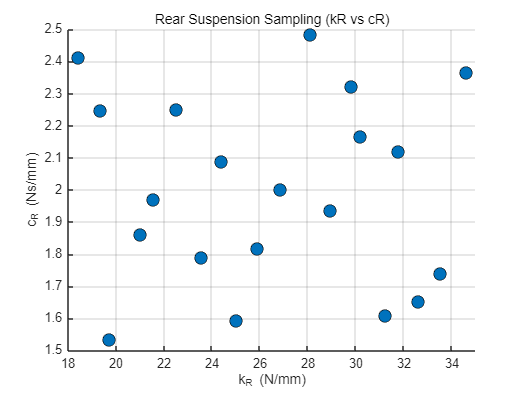


figure;
scatter(best_sample(:,3), best_sample(:,4), 100, 'o', 'filled', 'MarkerEdgeColor', 'k');
xlabel('k_R (N/mm)'); ylabel('c_R (Ns/mm)');
title('Rear Suspension Sampling (kR vs cR)');
xlim([18 35]); ylim([1.5 2.5]); grid on;


% LHS 샘플링 결과 출력 (숫자형 테이블)
disp('LHS 최종 샘플링 결과 (단위: k [N/mm], c [Ns/mm])');

LHS 최종 샘플링 결과 (단위: k [N/mm], c [Ns/mm])


T_lhs = table(best_sample(:,1), best_sample(:,2), best_sample(:,3), best_sample(:,4), ...
    'VariableNames', {'kF', 'cF', 'kR', 'cR'});
disp(T_lhs);

      kF        cF        kR        cR  
    ______    ______    ______    ______

    23.057    2.1274    31.253    1.6104
     29.69     1.605    26.868    2.0012
    32.408    2.0882    21.561    1.9707
    34.588    1.5758    25.006    1.5925
    21.318    2.4199    24.377    2.0895
    23.775     1.769     18.42    2.4121
    25.956    2.3813    33.526    1.7385
    33.518    1.8721    22.523    2.2515
     24.95    2.4527    23.563    1.7895
    18.142    1.6989    31.769    2.1198
    30.315    2.3351    21.003    1.8604
    19.841    1.5406    19.707     1.534
    22.171    2.1817    19.348    2.2476
    26.939    1.9857    32.609    1.6516
    28.033    2.2514    30.203    2.1665
    19.197    2.0328    29.838    2.3215
     31.43    1.8198    34.606     2.366
    32.643     2.237    28.948    1.9367
    24.661    1.7363    25.883     1.818
    29.029    1.9086     28.11     2.484



## Cosine-Based Speed Profile

Both pitch and roll simulations use the **same velocity profile**$v(t)$, which is defined as:


$$$$ 
v(t) = 
\begin{cases}
v_{max} \cdot \frac{1 - \cos\left(\frac{\pi t}{3}\right)}{2}, & 0 \leq t < 3 \\
v_{max}, & 3 \leq t < 7 \\
v_{max} \cdot \frac{1 + \cos\left(\frac{\pi (t - 7)}{3}\right)}{2}, & 7 \leq t \leq 10
\end{cases}
$$
$$


** 2. External Moment Models**

**Pitch Moment Model (Longitudinal Acceleration)**

- **Longitudinal acceleration** is derived from the time derivative of velocity:


$$a_x(t) = \frac{dv(t)}{dt}
$$


- The **external pitch moment** is generated by the product of longitudinal acceleration and the moment arm from CG:


$$M_\theta(t) = m_s \cdot a_x(t) \cdot h_{cg}
$$


**Roll Moment Model (Lateral Acceleration)**

- **Lateral acceleration** includes both centripetal and tangential components:


$$a_y(t) = \frac{v(t)^2}{R} + \frac{1}{R} \cdot \frac{dv(t)}{dt}
$$


- The **external roll moment** is then given by:


$$M_\phi(t) = m_s \cdot a_y(t) \cdot h_{cg}
$$


## Section 2: Pitch Dynamics

### 
$$$$
I_{yy} \cdot \ddot{\theta}(t) =
M_{\theta}(t)
- (k_f a^2 + k_r b^2) \cdot \theta(t)
- (c_f a^2 + c_r b^2) \cdot \dot{\theta}(t)
$$$$


이 섹션은 차량이 가속하거나 감속할 때 발생하는 **피치 모션(앞/뒤로 기울어짐)** 을 시뮬레이션합니다.

입력은 지수적으로 감소하는 피치 모멘트로 주어지며, 서스펜션 파라미터에 따라 피치 각도 θ(t) 및 각가속도 θ̈(t)가 어떻게 변하는지 계산합니다.

결과는 **RMS (Root Mean Square)** 값을 통해 전체적인 응답의 크기를 정량화합니다.

## Explanation: Pitch & Roll Dynamics Equations

1. Fundamental Principle: Newton–Euler Rotational Dynamics

The vehicle body is modeled as a rigid body with rotational degrees of freedom.

According to Newton–Euler rotational dynamics:


$$$$
\text{Moment of Inertia} \times \text{Angular Acceleration} = \text{External Moment} - \text{Restoring Moment}
$$
$$


**Pitch Dynamics Equation (Longitudinal Tilting)**


$$$$
I_{yy} \cdot \ddot{\theta}(t) =
M_{\theta}(t)
- (k_f a^2 + k_r b^2) \cdot \theta(t)
- (c_f a^2 + c_r b^2) \cdot \dot{\theta}(t)
$$$$



$$% Pitch Dynamics Parameters (LaTeX format for MATLAB)

% External Input Moment
$$
M_{\theta}(t):\ \text{Pitch moment input caused by acceleration or braking}
$$

% Spring Restoring Moment
$$
k_f a^2 + k_r b^2:\ \text{Restoring moment due to spring forces acting at distances } a, b \text{ from the center of gravity}
$$

% Damping Moment
$$
c_f a^2 + c_r b^2:\ \text{Damping moment proportional to pitch angular velocity}
$$
$$


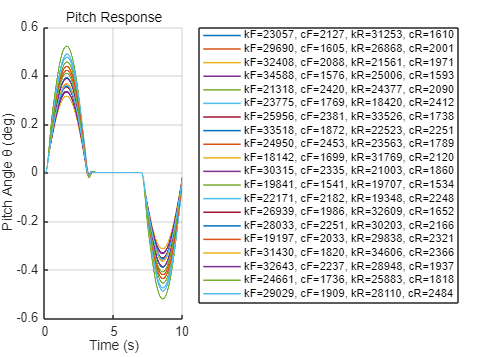

%% Pitch Dynamics Simulation
% 차량이 가속/등속/감속할 때 발생하는 피치 운동을 시뮬레이션합니다.
% 속도 변화에 따른 종방향 가속도를 기반으로 피치 모멘트를 계산하여 입력으로 사용합니다.

%% 차량 및 서스펜션 파라미터
m_s = 243;           % 스프렁 질량 [kg]
Iyy = 105;            % 피치 관성 모멘트 [kg·m²]
L = 1.11;            % 휠베이스 [m]
a = 0.61;            % 앞축까지 거리 [m]
b = L - a;           % 뒷축까지 거리 [m]
h_cg = 0.25;         % 질량 중심 높이 [m]

%% 시뮬레이션 시간 및 속도 프로파일
dt = 0.001;
t = 0:dt:10;         % 전체 시뮬레이션 시간 0~10초
v_max = 3.5;         % 목표 속도 [m/s] → 12.6 km/h

v = zeros(size(t));
a_x = zeros(size(t));
for i = 1:length(t)
    if t(i) < 3
        v(i) = v_max * 0.5 * (1 - cos(pi * t(i)/3));
        a_x(i) = v_max * (pi/6) * sin(pi * t(i)/3);
    elseif t(i) < 7
        v(i) = v_max;
        a_x(i) = 0;
    elseif t(i) <= 10
        tau = (t(i) - 7) / 3;
        v(i) = v_max * 0.5 * (1 + cos(pi * tau));
        a_x(i) = -v_max * (pi/6) * sin(pi * tau);
    end
end

% 가속도 및 피치 모멘트 계산
%a_x = [0 diff(v) / dt];                          % 가속도 [m/s²]

% 랜덤 진동 추가 (화이트 노이즈, ±5Nm)
rng(1);  % 재현 가능한 랜덤성 고정
noise = 5 * randn(size(t));                      % 노이즈 [Nm]

% 최종 피치 외력
M_profile = m_s * a_x * h_cg; % + noise;            % 피치 모멘트 [Nm]
M_theta_input = @(tt) interp1(t, M_profile, tt, 'linear', 'extrap');  % 입력 함수

%% 초기 조건
x0 = [0; 0];

%% 시뮬레이션 반복 실행
for i = 1:n_samples
    pf = params(i);  % 현재 샘플 파라미터

    % 상태방정식 정의
    model = @(t, x) [
        x(2);
        (M_theta_input(t) ...
        - (pf.k_f*a^2 + pf.k_r*b^2)*x(1) ...
        - (pf.c_f*a^2 + pf.c_r*b^2)*x(2)) / Iyy
    ];

    [~, x] = ode45(model, t, x0);
    theta = x(:,1);           % 피치 각도 θ(t)
    theta_dot = x(:,2);       % 피치 속도 θ̇(t)
    theta_ddot = zeros(size(t));

    % 각가속도 θ̈(t) 계산
    for j = 1:length(t)
        theta_ddot(j) = (M_theta_input(t(j)) ...
            - (pf.k_f*a^2 + pf.k_r*b^2)*theta(j) ...
            - (pf.c_f*a^2 + pf.c_r*b^2)*theta_dot(j)) / Iyy;
    end

    % 결과 저장 및 RMS 계산
    params(i).theta = theta;
    params(i).theta_dot = theta_dot;
    params(i).theta_ddot = theta_ddot;

    params(i).theta_rms = sqrt(mean((theta * 180/pi).^2));         % [deg]
    params(i).theta_dot_rms = sqrt(mean((theta_dot * 180/pi).^2)); % [deg/s]
    params(i).theta_ddot_rms = sqrt(mean((theta_ddot * 180/pi).^2)); % [deg/s²]
end

%% 피치 각도 응답 시각화
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).theta * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Pitch Angle θ (deg)');
title('Pitch Response'); xlim([0 10]); grid on;
legend({params.legend}, 'Location', 'northeastoutside');


%% 피치 속도 응답 시각화
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).theta_dot * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Pitch Velocity θ̇ (deg/s)');
title('Pitch Angular Velocity Response'); xlim([0 10]); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

%% 피치 가속도 응답 시각화
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).theta_ddot * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Pitch Acceleration θ̈ (deg/s²)');
title('Pitch Angular Acceleration Response'); xlim([0 10]); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

%% θ̇ RMS 시각화
figure; hold on;
colors = lines(n_samples);
for i = 1:n_samples
    bar(i, params(i).theta_dot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('θ̇_{rms} (deg/s)');
title('Pitch Angular Velocity RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

%% θ̈ RMS 시각화
figure; hold on;
for i = 1:n_samples
    bar(i, params(i).theta_ddot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('θ̈_{rms} (deg/s²)');
title('Pitch Angular Acceleration RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

%% RMS 결과 출력
fprintf('\n== Pitch RMS Results ==\n');


== Pitch RMS Results ==


for i = 1:n_samples
    fprintf('%s → θ_rms = %.4f deg, θ̇_rms = %.4f deg/s, θ̈_rms = %.4f deg/s²\n', ...
        params(i).legend, ...
        params(i).theta_rms, ...
        params(i).theta_dot_rms, ...
        params(i).theta_ddot_rms);
end

kF=23057, cF=2127, kR=31253, cR=1610 → θ_rms = 0.2139 deg, θ̇_rms = 0.2222 deg/s, θ̈_rms = 0.6326 deg/s²
kF=29690, cF=1605, kR=26868, cR=2001 → θ_rms = 0.1975 deg, θ̇_rms = 0.2064 deg/s, θ̈_rms = 0.6276 deg/s²
kF=32408, cF=2088, kR=21561, cR=1971 → θ_rms = 0.2009 deg, θ̇_rms = 0.2083 deg/s, θ̈_rms = 0.5921 deg/s²
kF=34588, cF=1576, kR=25006, cR=1593 → θ_rms = 0.1835 deg, θ̇_rms = 0.1931 deg/s, θ̈_rms = 0.6302 deg/s²
kF=21318, cF=2420, kR=24377, cR=2090 → θ_rms = 0.2496 deg, θ̇_rms = 0.2551 deg/s, θ̈_rms = 0.6382 deg/s²
kF=23775, cF=1769, kR=18420, cR=2412 → θ_rms = 0.2606 deg, θ̇_rms = 0.2678 deg/s, θ̈_rms = 0.6880 deg/s²
kF=25956, cF=2381, kR=33526, cR=1738 → θ_rms = 0.1943 deg, θ̇_rms = 0.2013 deg/s, θ̈_rms = 0.5711 deg/s²
kF=33518, cF=1872, kR=22523, cR=2251 → θ_rms = 0.1937 deg, θ̇_rms = 0.2011 deg/s, θ̈_rms = 0.5831 deg/s²
kF=24950, cF=2453, kR=23563, cR=1789 → θ_rms = 0.2309 deg, θ̇_rms = 0.2373 deg/s, θ̈_rms = 0.6210 deg/s²
kF=18142, cF=1699, kR=31769, cR=2120 → θ_rms = 0.2388 d

## Section 3: Roll Dynamics

### 
$$$$
I_{xx} \cdot \ddot{\phi}(t) =
M_{\phi}(t)
- (k_f t_f^2 + k_r t_r^2) \cdot \phi(t)
- (c_f t_f^2 + c_r t_r^2) \cdot \dot{\phi}(t)
$$$$


이 섹션은 차량이 커브를 돌거나 횡가속도를 받을 때 발생하는 **롤 모션(좌우 기울어짐)** 을 해석합니다.

입력은 `a_y`로부터 계산된 롤 모멘트이며, 서스펜션의 앞/뒤 스프링과 감쇠 특성에 따라 **롤 각도 φ(t)** 및 **롤 각가속도 φ̈(t)** 를 계산합니다.

피치와 마찬가지로 RMS 값을 통해 각 조합의 롤 응답을 비교할 수 있습니다.

## Explanation: Pitch & Roll Dynamics Equations

 1. Fundamental Principle: Newton–Euler Rotational Dynamics

The vehicle body is modeled as a rigid body with rotational degrees of freedom.

According to Newton–Euler rotational dynamics:


$$$$
\text{Moment of Inertia} \times \text{Angular Acceleration} = \text{External Moment} - \text{Restoring Moment}
$$
$$


**Roll Dynamics Equation (Lateral Tilting)**


$$$$
I_{xx} \cdot \ddot{\phi}(t) =
M_{\phi}(t)
- (k_f t_f^2 + k_r t_r^2) \cdot \phi(t)
- (c_f t_f^2 + c_r t_r^2) \cdot \dot{\phi}(t)
$$$$



$$% Roll Dynamics Parameters (LaTeX format for MATLAB)

% External Input Moment
$$
M_{\phi}(t):\ \text{Roll moment input caused by lateral acceleration during cornering}
$$

% Track Width Parameters
$$
t_f,\ t_r:\ \text{Front and rear track width (distance from CG to left/right suspension points)}
$$

% Structural Analogy to Pitch Dynamics
$$
\text{Structure mirrors that of pitch dynamics, with distances } a, b \text{ replaced by } t_f, t_r
$$
$$



$$$$
\begin{array}{ll}
m_s & \text{: Sprung mass} \quad (243\ \text{kg}) \\
I_{yy} & \text{: Pitch moment of inertia} \quad (105\ \text{kg} \cdot \text{m}^2) \\
I_{xx} & \text{: Roll moment of inertia} \quad (65\ \text{kg} \cdot \text{m}^2) \\
a & \text{: Distance from CG to front axle} \quad (0.61\ \text{m}) \\
b & \text{: Distance from CG to rear axle} \quad (0.5\ \text{m}) \\
t_f,\ t_r & \text{: Half of front/rear track width} \quad (0.55\ \text{m}) \\
h_{cg} & \text{: CG height from ground} \quad (0.25\ \text{m}) \\
k_f,\ k_r & \text{: Front/rear spring stiffness [N/m]} \\
c_f,\ c_r & \text{: Front/rear damping coefficient [Ns/m]}
\end{array}
$$
$$


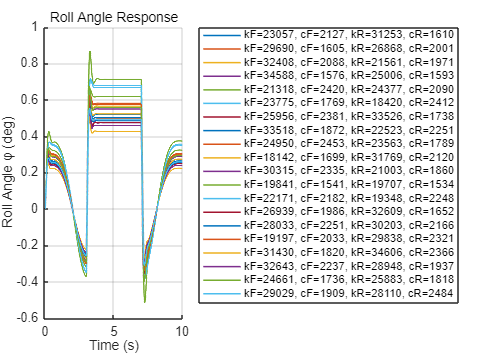

%% Roll Dynamics Simulation
% 차량이 속도 변화에 따라 회전 주행 시 발생하는 롤 운동을 시뮬레이션합니다.
% 속도 변화에 따른 횡가속도를 기반으로 롤 모멘트를 계산하여 입력으로 사용합니다.

%% 차량 파라미터
m_s = 243;            % 스프렁 질량 [kg]
Ixx = 65;             % 롤 관성 모멘트 [kg·m²]
t_f = 0.55; t_r = 0.55; % 전후륜 트레드 폭 [m]
R = 5;                % 회전 반경 [m]
h_cg = 0.25;          % 질량 중심 높이 [m]

%% 시뮬레이션 시간 및 속도/가속도 프로파일
dt = 0.001;
t = 0:dt:10;
v_max = 3.5;
v = zeros(size(t));
ay_profile = zeros(size(t));
for i = 1:length(t)
    if t(i) <= 3
        v(i) = v_max * 0.5 * (1 - cos(pi * t(i)/3));
        ay_profile(i) = (v_max^2 / R) * 0.25 * (pi/3)^2 * sin(pi * t(i)/3)^2 + ...
                        (v_max^2 / R) * 0.5 * (pi/3) * cos(pi * t(i)/3);
    elseif t(i) <= 7
        v(i) = v_max;
        ay_profile(i) = v_max^2 / R;
    elseif t(i) <= 10
        tau = (t(i) - 7) / 3;
        v(i) = v_max * 0.5 * (1 + cos(pi * tau));
        ay_profile(i) = (v_max^2 / R) * 0.25 * (pi/3)^2 * sin(pi * tau)^2 - ...
                        (v_max^2 / R) * 0.5 * (pi/3) * cos(pi * tau);
    end
end

% 롤 모멘트
M_phi = m_s * ay_profile * h_cg;
M_phi_input = @(tt) interp1(t, M_phi, tt, 'linear', 'extrap');

%% 초기 상태
x0 = [0; 0];

%% 시뮬레이션 반복
for i = 1:n_samples
    pf = params(i);
    roll_model = @(t_cur, x) [
        x(2);
        (M_phi_input(t_cur) ...
        - (pf.k_f * t_f^2 + pf.k_r * t_r^2) * x(1) ...
        - (pf.c_f * t_f^2 + pf.c_r * t_r^2) * x(2)) / Ixx
    ];

    [~, x_roll] = ode45(roll_model, t, x0);
    phi = x_roll(:,1);
    phi_dot = x_roll(:,2);
    phi_ddot = zeros(size(t));

    for j = 1:length(t)
        phi_ddot(j) = (M_phi_input(t(j)) ...
            - (pf.k_f * t_f^2 + pf.k_r * t_r^2) * phi(j) ...
            - (pf.c_f * t_f^2 + pf.c_r * t_r^2) * phi_dot(j)) / Ixx;
    end

    params(i).phi = phi;
    params(i).phi_dot = phi_dot;
    params(i).phi_ddot = phi_ddot;
    params(i).phi_rms = sqrt(mean((phi * 180/pi).^2));
    params(i).phi_dot_rms = sqrt(mean((phi_dot * 180/pi).^2));
    params(i).phi_ddot_rms = sqrt(mean((phi_ddot * 180/pi).^2));
end

%% 시각화
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).phi * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Roll Angle φ (deg)');
title('Roll Angle Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

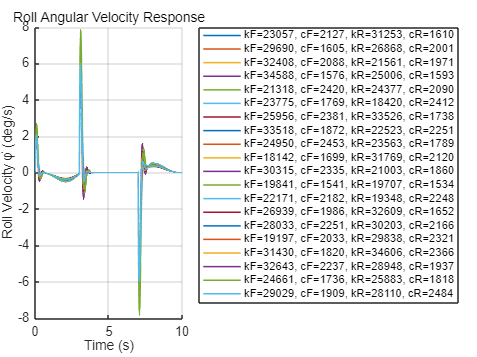


figure; hold on;
for i = 1:n_samples
    plot(t, params(i).phi_dot * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Roll Velocity φ̇ (deg/s)');
title('Roll Angular Velocity Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

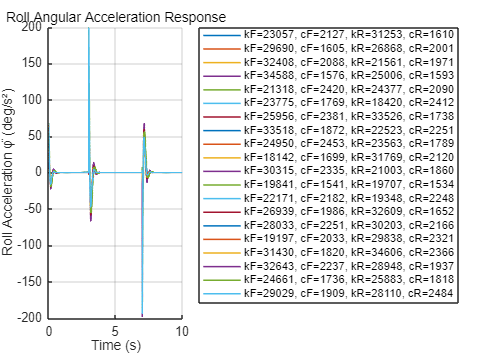


figure; hold on;
for i = 1:n_samples
    plot(t, params(i).phi_ddot * 180/pi, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Roll Acceleration φ̈ (deg/s²)');
title('Roll Angular Acceleration Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

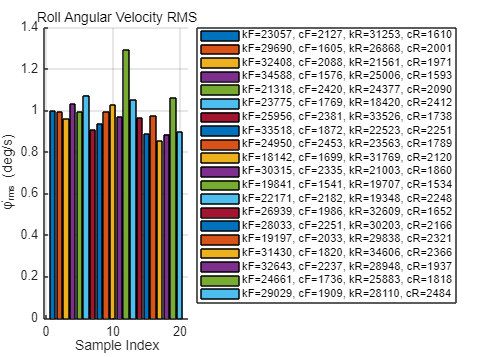


%% φ̇ RMS 바 플롯
figure; hold on;
colors = lines(n_samples);
for i = 1:n_samples
    bar(i, params(i).phi_dot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('φ̇_{rms} (deg/s)');
title('Roll Angular Velocity RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

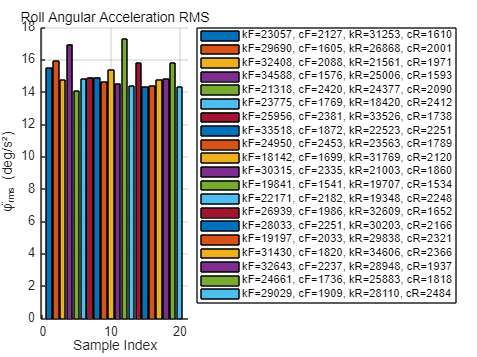


%% φ̈ RMS 바 플롯
figure; hold on;
for i = 1:n_samples
    bar(i, params(i).phi_ddot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('φ̈_{rms} (deg/s²)');
title('Roll Angular Acceleration RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');


%% RMS 출력
fprintf('\n== Roll RMS Results ==\n');


== Roll RMS Results ==


for i = 1:n_samples
    fprintf('%s → φ_rms = %.4f deg, φ̇_rms = %.4f deg/s, φ̈_rms = %.4f deg/s²\n', ...
        params(i).legend, ...
        params(i).phi_rms, ...
        params(i).phi_dot_rms, ...
        params(i).phi_ddot_rms);
end

kF=23057, cF=2127, kR=31253, cR=1610 → φ_rms = 0.3651 deg, φ̇_rms = 0.9963 deg/s, φ̈_rms = 15.5014 deg/s²
kF=29690, cF=1605, kR=26868, cR=2001 → φ_rms = 0.3513 deg, φ̇_rms = 0.9930 deg/s, φ̈_rms = 15.9308 deg/s²
kF=32408, cF=2088, kR=21561, cR=1971 → φ_rms = 0.3663 deg, φ̇_rms = 0.9597 deg/s, φ̈_rms = 14.7349 deg/s²
kF=34588, cF=1576, kR=25006, cR=1593 → φ_rms = 0.3351 deg, φ̇_rms = 1.0302 deg/s, φ̈_rms = 16.9427 deg/s²
kF=21318, cF=2420, kR=24377, cR=2090 → φ_rms = 0.4291 deg, φ̇_rms = 0.9925 deg/s, φ̈_rms = 14.0475 deg/s²
kF=23775, cF=1769, kR=18420, cR=2412 → φ_rms = 0.4651 deg, φ̇_rms = 1.0728 deg/s, φ̈_rms = 14.8103 deg/s²
kF=25956, cF=2381, kR=33526, cR=1738 → φ_rms = 0.3328 deg, φ̇_rms = 0.9065 deg/s, φ̈_rms = 14.8994 deg/s²
kF=33518, cF=1872, kR=22523, cR=2251 → φ_rms = 0.3528 deg, φ̇_rms = 0.9341 deg/s, φ̈_rms = 14.8968 deg/s²
kF=24950, cF=2453, kR=23563, cR=1789 → φ_rms = 0.4058 deg, φ̇_rms = 0.9918 deg/s, φ̈_rms = 14.6437 deg/s²
kF=18142, cF=1699, kR=31769, cR=2120 → φ_rms =

## Section 4: Z-axis (Heave) Dynamics

### 
$$$$
m_s \cdot \ddot{z}(t) +
(c_f + c_r) \cdot \dot{z}(t) +
(k_f + k_r) \cdot z(t) =
F_z(t)
$$

\quad \text{with} \quad
$$
F_z(t) = \frac{m_s \cdot a_y(t) \cdot h_{cg}}{t_{\text{track}} / 2}
$$$$


이 섹션에서는 차량의 무게 중심이 위아래로 흔들리는 **수직 운동(heave)** 을 계산합니다.

입력은 횡가속도로 인해 좌우 바퀴에 가해지는 수직 하중 이동이며, 이는 수직방향 외력(Fz_transfer)으로 작용합니다.

결과적으로 수직 변위 z(t) 및 가속도 ẍ(t)를 계산하고, 수직 진동의 크기를 RMS로 평가합니다.


$$\begin{array}{ll}
\textbf{Term} & \textbf{Physical Meaning} \\
m_s \cdot \ddot{z}(t) & \text{Inertial force due to vertical acceleration of the sprung mass} \\
(c_f + c_r) \cdot \dot{z}(t) & \text{Total damping force from front and rear dampers} \\
(k_f + k_r) \cdot z(t) & \text{Total restoring force from front and rear springs} \\
F_z(t) & \text{External vertical force (e.g., load transfer due to roll during cornering)}
\end{array}
$$



$$F_z(t) = \frac{M_{\text{roll}}}{t_{\text{track}}/2} = \frac{m_s \cdot a_y(t) \cdot h_{cg}}{t_{\text{track}}/2}
$$


%% Section 4: Z-axis Heave Dynamics Simulation
% 이 섹션에서는 차량의 Z축 수직운동(z)의 응답과 그 가속도 RMS(ẍ)를 분석합니다.
% 입력은 횡가속도로 인한 수직 하중 이동을 외력으로 반영합니다.
% 모델: M * z'' + (c_f + c_r) * z' + (k_f + k_r) * z = Fz_transfer

%% 차량 파라미터
m_s = 243;           % 스프렁 질량 [kg]
t_track = 0.55;       % 트레드 폭 [m]
h_cg = 0.25;         % 질량 중심 높이 [m]
R = 5;               % 회전 반경 [m]

%% 시뮬레이션 시간 및 속도 프로파일
dt = 0.001;
t = 0:dt:10;
v_max = 3.5;

v = zeros(size(t));
a_x = zeros(size(t));
for i = 1:length(t)
    if t(i) < 3
        v(i) = v_max * 0.5 * (1 - cos(pi * t(i)/3));
        a_x(i) = v_max * (pi/6) * sin(pi * t(i)/3);
    elseif t(i) < 7
        v(i) = v_max;
        a_x(i) = 0;
    elseif t(i) <= 10
        tau = (t(i) - 7) / 3;
        v(i) = v_max * 0.5 * (1 + cos(pi * tau));
        a_x(i) = -v_max * (pi/6) * sin(pi * tau);
    end
end

%% 횡가속도 및 외력 계산
ay_profile = v.^2 / R;
rng(1); noise = 20 * randn(size(t));  % ±20N 수준 노이즈
Fz_transfer_profile = (m_s * ay_profile * h_cg) / (t_track / 2) % + noise;

Fz_transfer_profile =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


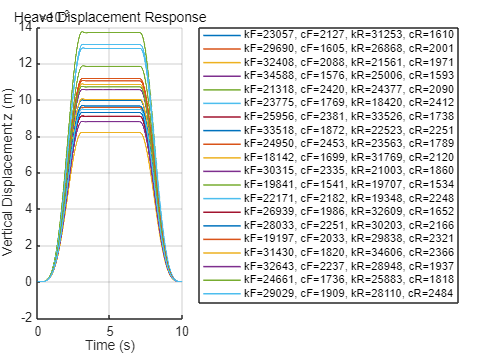


%% 초기 조건
z0 = [0; 0];

%% 시뮬레이션 반복 실행
for i = 1:n_samples
    pf = params(i);  % LHS로부터 샘플링된 서스펜션 파라미터

    % 입력 외력 보간 함수
    Fz_input = @(tt) interp1(t, Fz_transfer_profile, tt, 'linear', 'extrap');

    % 상태방정식 (2차 시스템)
    z_model = @(t, x) [
        x(2);
        (Fz_input(t) - (pf.k_f + pf.k_r)*x(1) - (pf.c_f + pf.c_r)*x(2)) / m_s
    ];

    % ODE 시뮬레이션
    [~, x_z] = ode45(z_model, t, z0);
    z = x_z(:,1);
    z_dot = x_z(:,2);
    z_ddot = gradient(z_dot, t);

    % 저장
    params(i).z = z;
    params(i).z_dot = z_dot;
    params(i).z_ddot = z_ddot;
    params(i).z_rms = sqrt(mean(z.^2));
    params(i).z_ddot_rms = sqrt(mean(z_ddot.^2));
end

%% 시각화 - z 응답
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).z, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Vertical Displacement z (m)');
title('Heave Displacement Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

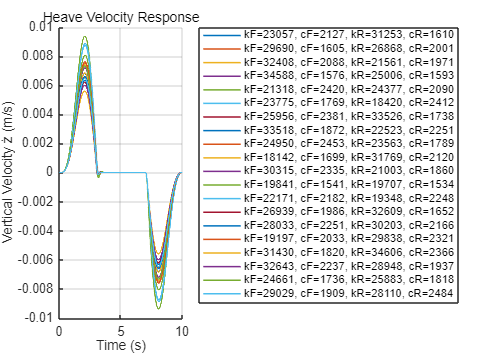


%% 시각화 - ż 응답
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).z_dot, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Vertical Velocity ż (m/s)');
title('Heave Velocity Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

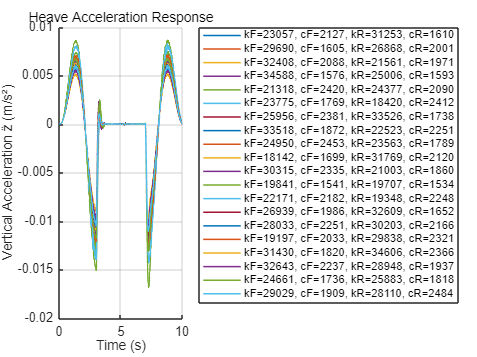


%% 시각화 - z̈ 응답
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).z_ddot, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Vertical Acceleration z̈ (m/s²)');
title('Heave Acceleration Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

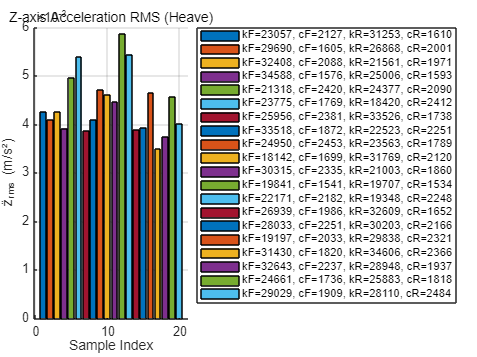


%% 바 플롯 - z̈ RMS
figure; hold on;
colors = lines(n_samples);
for i = 1:n_samples
    bar(i, params(i).z_ddot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('z̈_{rms} (m/s²)');
title('Z-axis Acceleration RMS (Heave)'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');


%% 결과 출력
fprintf('\n== Z-axis Heave RMS Results ==\n');


== Z-axis Heave RMS Results ==


for i = 1:n_samples
    fprintf('%s → z_rms = %.4f m, z̈_rms = %.4f m/s²\n', ...
        params(i).legend, ...
        params(i).z_rms, ...
        params(i).z_ddot_rms);
end

kF=23057, cF=2127, kR=31253, cR=1610 → z_rms = 0.0075 m, z̈_rms = 0.0042 m/s²
kF=29690, cF=1605, kR=26868, cR=2001 → z_rms = 0.0072 m, z̈_rms = 0.0041 m/s²
kF=32408, cF=2088, kR=21561, cR=1971 → z_rms = 0.0075 m, z̈_rms = 0.0043 m/s²
kF=34588, cF=1576, kR=25006, cR=1593 → z_rms = 0.0068 m, z̈_rms = 0.0039 m/s²
kF=21318, cF=2420, kR=24377, cR=2090 → z_rms = 0.0089 m, z̈_rms = 0.0050 m/s²
kF=23775, cF=1769, kR=18420, cR=2412 → z_rms = 0.0096 m, z̈_rms = 0.0054 m/s²
kF=25956, cF=2381, kR=33526, cR=1738 → z_rms = 0.0068 m, z̈_rms = 0.0039 m/s²
kF=33518, cF=1872, kR=22523, cR=2251 → z_rms = 0.0073 m, z̈_rms = 0.0041 m/s²
kF=24950, cF=2453, kR=23563, cR=1789 → z_rms = 0.0084 m, z̈_rms = 0.0047 m/s²
kF=18142, cF=1699, kR=31769, cR=2120 → z_rms = 0.0081 m, z̈_rms = 0.0046 m/s²
kF=30315, cF=2335, kR=21003, cR=1860 → z_rms = 0.0079 m, z̈_rms = 0.0045 m/s²
kF=19841, cF=1541, kR=19707, cR=1534 → z_rms = 0.0103 m, z̈_rms = 0.0059 m/s²
kF=22171, cF=2182, kR=19348, cR=2248 → z_rms = 0.0098 m, z̈_rms 

## Section 5: Lateral Dynamics Simulation

### 
$$$$
m_s \cdot \ddot{y}(t) +
(c_f + c_r) \cdot \dot{y}(t) +
(k_f + k_r) \cdot y(t) =
m_s \cdot a_y(t)
$$$$


이 섹션은 차량의 질량 중심이 좌우로 흔들리는 **횡 방향 진동(lateral sway)** 을 해석합니다.

입력은 차량이 곡선을 돌 때 발생하는 횡가속도에 의한 측면 외력 Fy(t)이며, 이 외력이 차량의 좌우 흔들림을 유도합니다.

해석을 통해 측방 이동량 y(t) 및 횡 가속도 ẏ̈(t)를 얻고, 이를 RMS 값으로 요약합니다.


$$\begin{array}{ll}
\textbf{Term} & \textbf{Physical Meaning} \\
m_s \cdot \ddot{y}(t) & \text{Inertial force from lateral acceleration of the CG} \\
(c_f + c_r) \cdot \dot{y}(t) & \text{Damping force opposing lateral motion} \\
(k_f + k_r) \cdot y(t) & \text{Restoring force resisting lateral displacement (can include anti-roll bar effects)} \\
m_s \cdot a_y(t) & \text{Lateral force input due to cornering maneuver}
\end{array}
$$



$$% Lateral acceleration
$$a_y(t) = \frac{v(t)^2}{R}$$

% External lateral force
$$F_y(t) = m_s \cdot a_y(t)$$
$$


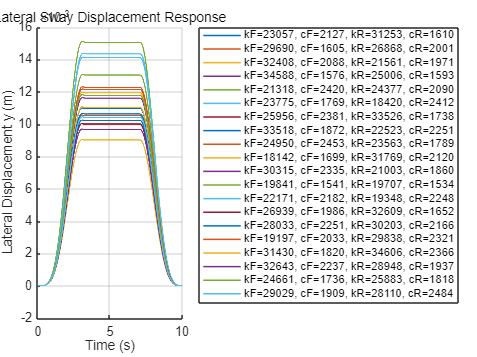

%% Section 5: Lateral Dynamics Simulation
% 이 섹션에서는 차량 질량 중심의 좌우 흔들림(lateral motion)을 계산합니다.
% 횡가속도에 의해 차량은 원심력 방향으로 힘을 받으며, 서스펜션에 의해 제어됩니다.
% 모델: M * y'' + (c_f + c_r) * y' + (k_f + k_r) * y = F_y(t)

%% 차량 파라미터
m_s = 243;         % 스프렁 질량 [kg]
R = 5;             % 회전 반경 [m]
t_track = 0.55;     % 트레드 폭 [m]

%% 시뮬레이션 시간 및 속도 프로파일
dt = 0.001;
t = 0:dt:10;
v_max = 3.5;

v = zeros(size(t));
a_x = zeros(size(t));
for i = 1:length(t)
    if t(i) < 3
        v(i) = v_max * 0.5 * (1 - cos(pi * t(i)/3));
        a_x(i) = v_max * (pi/6) * sin(pi * t(i)/3);
    elseif t(i) < 7
        v(i) = v_max;
        a_x(i) = 0;
    elseif t(i) <= 10
        tau = (t(i) - 7) / 3;
        v(i) = v_max * 0.5 * (1 + cos(pi * tau));
        a_x(i) = -v_max * (pi/6) * sin(pi * tau);
    end
end

%% 횡가속도 및 외력 프로파일
ay_profile = v.^2 / R;
rng(2);
noise = 20 * randn(size(t));
Fy_profile = m_s * ay_profile; % + noise;
Fy_interp = @(tq) interp1(t, Fy_profile, tq, 'linear', 'extrap');

%% 초기 조건
y0 = [0; 0];

%% 색상 지정
colors = lines(n_samples);

%% 시뮬레이션
for i = 1:n_samples
    pf = params(i);

    y_model = @(t_cur, x) [
        x(2);
        (Fy_interp(t_cur) - (pf.k_f + pf.k_r) * x(1) - (pf.c_f + pf.c_r) * x(2)) / m_s
    ];

    [~, x_y] = ode45(y_model, t, y0);
    y = x_y(:,1);
    y_dot = x_y(:,2);
    y_ddot = gradient(y_dot, t);

    params(i).y = y;
    params(i).y_dot = y_dot;
    params(i).y_ddot = y_ddot;
    params(i).y_rms = sqrt(mean(y.^2));
    params(i).y_dot_rms = sqrt(mean(y_dot.^2));
    params(i).y_ddot_rms = sqrt(mean(y_ddot.^2));
end

%% 시각화: Lateral Displacement
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).y, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Lateral Displacement y (m)');
title('Lateral Sway Displacement Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

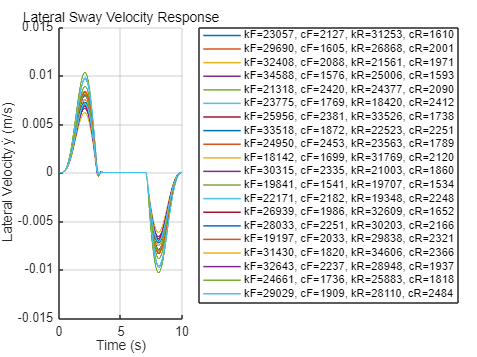


%% 시각화: Lateral Velocity
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).y_dot, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Lateral Velocity ẏ (m/s)');
title('Lateral Sway Velocity Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

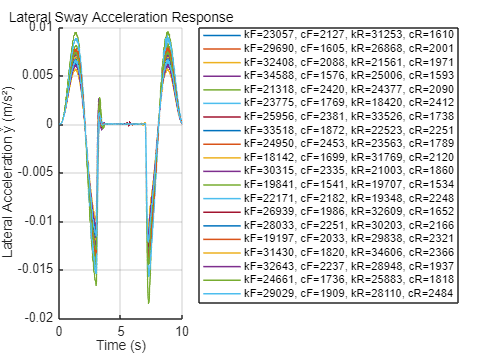


%% 시각화: Lateral Acceleration
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).y_ddot, 'LineWidth', 1.2);
end
xlabel('Time (s)'); ylabel('Lateral Acceleration ẏ̈ (m/s²)');
title('Lateral Sway Acceleration Response'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');

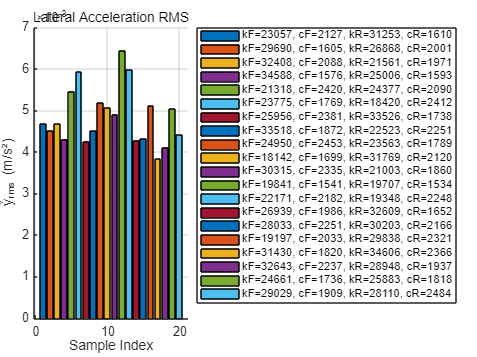


%% RMS Bar Plot: Acceleration
figure; hold on;
for i = 1:n_samples
    bar(i, params(i).y_ddot_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('ẏ̈_{rms} (m/s²)');
title('Lateral Acceleration RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');


%% 출력
fprintf('\n== Lateral Dynamics RMS Results ==\n');


== Lateral Dynamics RMS Results ==


for i = 1:n_samples
    fprintf('%s → y_rms = %.4f m, ẏ̇_rms = %.4f m/s, ẏ̈_rms = %.4f m/s²\n', ...
        params(i).legend, ...
        params(i).y_rms, ...
        params(i).y_dot_rms, ...
        params(i).y_ddot_rms);
end

kF=23057, cF=2127, kR=31253, cR=1610 → y_rms = 0.0082 m, ẏ̇_rms = 0.0035 m/s, ẏ̈_rms = 0.0047 m/s²
kF=29690, cF=1605, kR=26868, cR=2001 → y_rms = 0.0079 m, ẏ̇_rms = 0.0034 m/s, ẏ̈_rms = 0.0045 m/s²
kF=32408, cF=2088, kR=21561, cR=1971 → y_rms = 0.0083 m, ẏ̇_rms = 0.0035 m/s, ẏ̈_rms = 0.0047 m/s²
kF=34588, cF=1576, kR=25006, cR=1593 → y_rms = 0.0075 m, ẏ̇_rms = 0.0032 m/s, ẏ̈_rms = 0.0043 m/s²
kF=21318, cF=2420, kR=24377, cR=2090 → y_rms = 0.0098 m, ẏ̇_rms = 0.0042 m/s, ẏ̈_rms = 0.0055 m/s²
kF=23775, cF=1769, kR=18420, cR=2412 → y_rms = 0.0106 m, ẏ̇_rms = 0.0045 m/s, ẏ̈_rms = 0.0059 m/s²
kF=25956, cF=2381, kR=33526, cR=1738 → y_rms = 0.0075 m, ẏ̇_rms = 0.0032 m/s, ẏ̈_rms = 0.0043 m/s²
kF=33518, cF=1872, kR=22523, cR=2251 → y_rms = 0.0080 m, ẏ̇_rms = 0.0034 m/s, ẏ̈_rms = 0.0045 m/s²
kF=24950, cF=2453, kR=23563, cR=1789 → y_rms = 0.0092 m, ẏ̇_rms = 0.0039 m/s, ẏ̈_rms = 0.0052 m/s²
kF=18142, cF=1699, kR=31769, cR=2120 → y_rms = 0.0090 m, ẏ̇_rms = 0.0038 m/s, ẏ̈_rms = 0.0051 m/s²
kF=30315, 

## Section 6: Yaw Rate Dynamics Simulation

### 
$$$$
I_z \cdot \dot{r}(t) +
(c_f a^2 + c_r b^2) \cdot r(t) =
M_{\text{yaw}}(t)
$$

\quad \text{with} \quad
$$
M_{\text{yaw}}(t) \approx
m_s \cdot \frac{v^2}{L} \cdot \tan(\delta) \cdot h_{cg}
$$$$


이 섹션은 차량에 조향 입력(δ)이 주어졌을 때 발생하는 **요레이트(yaw rate, ψ̇)** 동역학을 시뮬레이션합니다.

조향각에 의해 유도된 입력 모멘트를 기반으로, 차량이 얼마나 빠르게 방향을 바꾸는지를 나타내는 yaw rate r(t)와 **Yaw Rate Gain (r/δ)** 를 계산합니다.

이 값은 차량의 선회 민감도 및 회전 응답 특성을 나타내는 핵심 지표이며, 각 서스펜션 샘플의 회전 특성을 비교하는 데 유용합니다.


$$\begin{array}{ll}
\textbf{Term} & \textbf{Meaning} \\
I_z \cdot \dot{r}(t) & \mbox{Yaw acceleration due to the moment of inertia} \\
(c_f a^2 + c_r b^2) \cdot r(t) & \mbox{Damping torque from front and rear dampers} \\
M_{\text{yaw}}(t) & \mbox{External yaw moment induced by steering input} \\
m_s & \mbox{Sprung mass} \\
\frac{v^2}{L} & \mbox{Centripetal acceleration based on path curvature} \\
\tan(\delta) & \mbox{Steering input (steering angle)} \\
h_{cg} & \mbox{Height of CG, acting as a moment arm for yaw torque} \\
\end{array}
$$



$$\[
\delta \approx \tan^{-1}\left(\frac{L}{R}\right) = \tan^{-1}\left(\frac{1.11}{5}\right) \approx 12.6^\circ
\]
$$



$$a_y(t) = \frac{v^2}{R}
\quad \Rightarrow \quad
M_{\text{yaw}}(t) \approx m_s \cdot \frac{v^2}{L} \cdot \tan(\delta) \cdot h_{cg}
$$



$$I_z \cdot \dot{r}(t) + \left(c_f a^2 + c_r b^2\right) \cdot r(t) = M_{\text{yaw}}(t)
$$



$$\dot{r}(t) = \frac{M_{\text{yaw}}(t) - \left(c_f a^2 + c_r b^2\right) \cdot r(t)}{I_z}
$$



$$\text{Yaw Rate Gain: } \quad \frac{r(t)}{\delta}
$$


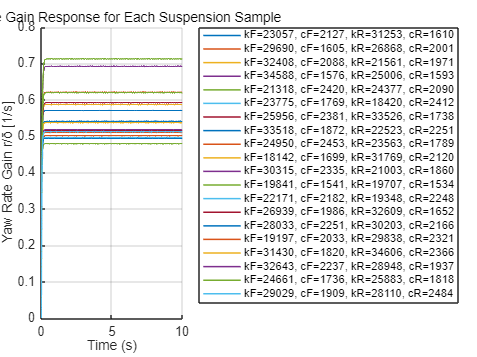

%% Section 6: Yaw Rate Dynamics Simulation
% 이 섹션에서는 조향 입력(δ)에 따른 차량의 Yaw Rate (r = dψ/dt) 동역학을 계산합니다.
% 모델: I_z * r_dot + C_total * r = M_input (yaw moment)
% 여기서 M_input은 조향각 δ에 의해 유도된 횡력 차이로 근사됨

% 차량 파라미터
Iz = 45;               % Yaw moment of inertia [kg*m^2]
delta = deg2rad(12.6);    % 조향 입력 (정상 입력 12.6도 가정)
v = 3.5;          % 속도 [m/s]
L = 1.11;               % 휠베이스
a = 0.61; b = L - a;

% 입력 모멘트 (근사)
M_input = @(t) m_s * v^2 / L * tan(delta) * h_cg;

r0 = 0;  % 초기 yaw rate
for i = 1:n_samples
    pf = params(i);

    % Total damping: 앞뒤 거리 반영
    C_total = pf.c_f * a^2 + pf.c_r * b^2;

    % Yaw rate 모델
    yaw_model = @(t, r) (M_input(t) - C_total * r) / Iz;

    [~, r] = ode45(@(t, r) yaw_model(t, r), t, r0);
    r = r(:);  % ensure column vector

    yaw_gain = r / delta;  % yaw rate gain [1/s per rad]

    params(i).yaw_rate = r;
    params(i).yaw_gain = yaw_gain;
    params(i).yaw_gain_rms = sqrt(mean(yaw_gain.^2));
end

% 시각화: Yaw Rate Gain plot
figure; hold on;
for i = 1:n_samples
    plot(t, params(i).yaw_gain, 'LineWidth', 1.2);
end
xlabel('Time (s)');
ylabel('Yaw Rate Gain r/δ [1/s]');
title('Yaw Rate Gain Response for Each Suspension Sample');
legend({params.legend}, 'Location', 'northeastoutside'); grid on;

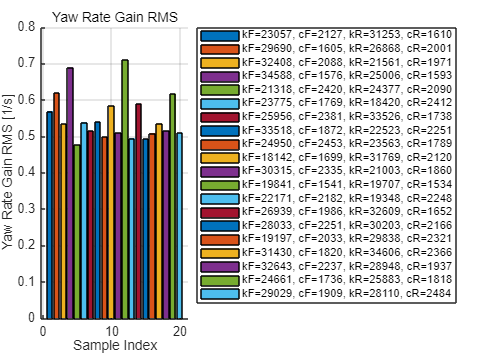


% Bar plot of yaw gain RMS
figure; hold on;
for i = 1:n_samples
    bar(i, params(i).yaw_gain_rms, 'FaceColor', colors(i,:));
end
xlabel('Sample Index'); ylabel('Yaw Rate Gain RMS [1/s]');
title('Yaw Rate Gain RMS'); grid on;
legend({params.legend}, 'Location', 'northeastoutside');


% 출력
fprintf('\n== Yaw Rate Gain RMS Results ==\n');


== Yaw Rate Gain RMS Results ==


for i = 1:n_samples
    fprintf('%s → Yaw Gain RMS = %.4f [1/s]\n', ...
        params(i).legend, ...
        params(i).yaw_gain_rms);
end

kF=23057, cF=2127, kR=31253, cR=1610 → Yaw Gain RMS = 0.5690 [1/s]
kF=29690, cF=1605, kR=26868, cR=2001 → Yaw Gain RMS = 0.6190 [1/s]
kF=32408, cF=2088, kR=21561, cR=1971 → Yaw Gain RMS = 0.5353 [1/s]
kF=34588, cF=1576, kR=25006, cR=1593 → Yaw Gain RMS = 0.6898 [1/s]
kF=21318, cF=2420, kR=24377, cR=2090 → Yaw Gain RMS = 0.4778 [1/s]
kF=23775, cF=1769, kR=18420, cR=2412 → Yaw Gain RMS = 0.5388 [1/s]
kF=25956, cF=2381, kR=33526, cR=1738 → Yaw Gain RMS = 0.5146 [1/s]
kF=33518, cF=1872, kR=22523, cR=2251 → Yaw Gain RMS = 0.5396 [1/s]
kF=24950, cF=2453, kR=23563, cR=1789 → Yaw Gain RMS = 0.4998 [1/s]
kF=18142, cF=1699, kR=31769, cR=2120 → Yaw Gain RMS = 0.5847 [1/s]
kF=30315, cF=2335, kR=21003, cR=1860 → Yaw Gain RMS = 0.5095 [1/s]
kF=19841, cF=1541, kR=19707, cR=1534 → Yaw Gain RMS = 0.7097 [1/s]
kF=22171, cF=2182, kR=19348, cR=2248 → Yaw Gain RMS = 0.4948 [1/s]
kF=26939, cF=1986, kR=32609, cR=1652 → Yaw Gain RMS = 0.5899 [1/s]
kF=28033, cF=2251, kR=30203, cR=2166 → Yaw Gain RMS = 0.4928 [

## Full RMS Summary Table

이 마지막 섹션에서는 위의 각 섹션에서 계산된 **Pitch, Roll, Heave, Lateral, Yaw** 동역학 응답들의 RMS 값을 모두 통합하여 하나의 테이블로 정리합니다.

이를 통해 각 서스펜션 세트에 대한 종합적인 거동을 수치적으로 비교할 수 있으며, 설계 최적화나 민감도 분석 등에 활용 가능합니다.

%% Full RMS Summary Table (Pitch + Roll + Heave + Lateral)
theta_rms_all      = [params.theta_rms]';
theta_ddot_rms_all = [params.theta_ddot_rms]';
phi_rms_all        = [params.phi_rms]';
phi_ddot_rms_all   = [params.phi_ddot_rms]';
z_rms_all          = [params.z_rms]';
z_ddot_rms_all     = [params.z_ddot_rms]';
y_rms_all          = [params.y_rms]';
y_ddot_rms_all     = [params.y_ddot_rms]';
yaw_gain_rms_all = [params.yaw_gain_rms]';

RMS_Table = table(theta_rms_all, theta_ddot_rms_all, ...
                  phi_rms_all,   phi_ddot_rms_all, ...
                  z_rms_all,     z_ddot_rms_all, ...
                  y_rms_all,     y_ddot_rms_all, ...
                  yaw_gain_rms_all, ...
    'VariableNames', {'theta_rms', 'theta_ddot_rms', ...
                      'phi_rms',   'phi_ddot_rms', ...
                      'z_rms',     'z_ddot_rms', ...
                      'y_rms',     'y_ddot_rms', ...
                      'yaw_gain_rms'});

disp('== Full RMS Summary Table (Pitch, Roll, Heave, Lateral, Yaw) ==');

== Full RMS Summary Table (Pitch, Roll, Heave, Lateral, Yaw) ==


disp(RMS_Table);

    theta_rms    theta_ddot_rms    phi_rms    phi_ddot_rms      z_rms      z_ddot_rms      y_rms      y_ddot_rms    yaw_gain_rms
    _________    ______________    _______    ____________    _________    __________    _________    __________    ____________

     0.21395        0.63257        0.36506       15.501       0.0074869    0.0042489     0.0082356    0.0046739       0.56902   
      0.1975        0.62761        0.35128       15.931       0.0071897    0.0040921     0.0079086    0.0045015       0.61899   
     0.20092        0.59209        0.36625       14.735       0.0075338    0.0042544     0.0082872    0.0046799       0.53526   
     0.18353        0.63017        0.33508       16.943       0.0068239     0.003914     0.0075063    0.0043056        0.6898   
     0.24962        0.63824         0.4291       14.048       0.0088959    0.0049621     0.0097855      0.00546        0.4778   
      0.2606        0.68801         0.4651        14.81       0.0096344    0.0053829      0.0105

## 설계 목적별 분류 

**1. 주행 안정성 (Handling Stability)**

차량의 제어 가능성과 선회 안정성, 타이어 접지력 유지와 관련된 동특성 지표

**2. 승차감 (Ride Comfort)**

탑승자의 신체 불쾌감이나 멀미, 피로감 등 감각적 편안함과 직결

## Section 7: GPR Surrogate Model & Weighted Score Evaluation

이 섹션에서는 Gaussian Process Regression (GPR)을 이용하여 대리모델을 구성하고, 주행 안정성(Handling Stability) 및 승차감(Ride Comfort) 점수를 계산합니다.

각 성능 지표는 0~1 사이로 정규화되고, 가중치를 곱해 점수를 생성합니다

.$x_{\text{norm}} = \frac{x - \min(x)}{\max(x) - \min(x)}
$


$$\[
  \text{Handling Score} = 0.4 \cdot f_{\text{Yaw}} + 0.35 \cdot (1 - f_{\text{Roll}}) + 0.25 \cdot (1 - f_{\text{Lat}})
  \]
  \[
  \text{Comfort Score} = 0.3 \cdot (1 - f_{\text{Pitch}}) + 0.25 \cdot (1 - f_{\text{Roll}}) + 0.45 \cdot (1 - f_{\text{Heave}})
  \]
$$


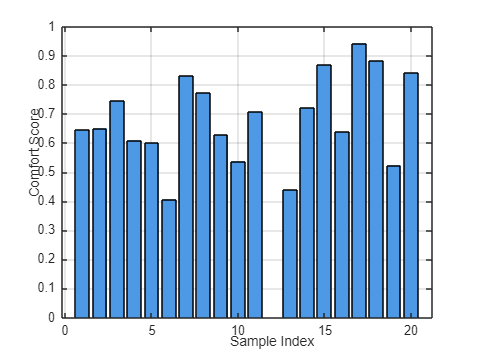

%% 입력 변수 (Design Variables)
X = [ [params.k_f]' , [params.c_f]' , [params.k_r]' , [params.c_r]' ];  % size: (20x4)

%% 출력 변수 (Objective Indicators)
% 1. 주행 안정성: yaw_gain_rms, phi_rms, y_ddot_rms
yaw_gain_all = [params.yaw_gain_rms]';
roll_angle_all = [params.phi_rms]';
lat_acc_all = [params.y_ddot_rms]';

% 2. 승차감: pitch_dot_rms, roll_acc_rms, z_rms
pitch_acc_all = [params.theta_ddot_rms]';
roll_acc_all = [params.phi_ddot_rms]';
heave_all = [params.z_rms]';

%% 정규화 (Min-Max)
normalize = @(x) (x - min(x)) / (max(x) - min(x));

yaw_norm  = normalize(yaw_gain_all);
roll_norm = normalize(roll_angle_all);
lat_norm  = normalize(lat_acc_all);

pitch_acc_norm = normalize(pitch_acc_all);
roll_acc_norm = normalize(roll_acc_all);
heave_norm = normalize(heave_all);

%% 가중치 합산 (일반적인 상황을 가정하여서 가중치를 부여) 그러나 회전상황에서 이런 파라미터는 중요치않더라" 논리적

Handling_Score = 0.4 * yaw_norm + 0.35 * (1 - roll_norm) + 0.25 * (1 - lat_norm);
Comfort_Score  = 0.3 * (1 - pitch_acc_norm) + 0.25 * (1 - roll_acc_norm) + 0.45 * (1 - heave_norm);

%% 결과 저장
for i = 1:length(params)
    params(i).handling_score = Handling_Score(i);
    params(i).comfort_score = Comfort_Score(i);
end

%% GPR 대리모델 학습 (예: Comfort Score 예측 모델)
gprModel_comfort = fitrgp(X, Comfort_Score, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

gprModel_handling = fitrgp(X, Handling_Score, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

%% 시각화 (Comfort Score bar plot)
figure;
bar(Comfort_Score, 'FaceColor', [0.3 0.6 0.9]); grid on;
xlabel('Sample Index'); ylabel('Comfort Score');
title('Ride Comfort Score (Normalized & Weighted)');

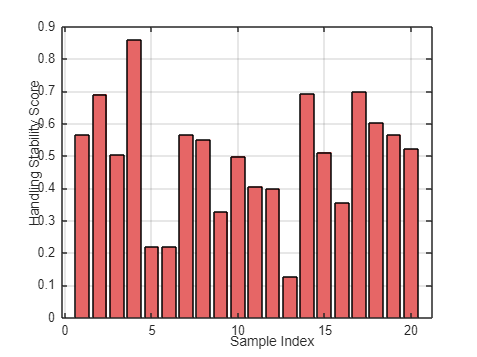


%% 시각화 (Handling Score bar plot)
figure;
bar(Handling_Score, 'FaceColor', [0.9 0.4 0.4]); grid on;
xlabel('Sample Index'); ylabel('Handling Stability Score');
title('Handling Stability Score (Normalized & Weighted)');

## Section 8: 각 지표별 GPR 대리모델 시각화 (kF vs cF 기준)

입력 차원이 4D이기 때문에 전부 시각화는 불가능하고, 두 개의 변수를 고정하고 나머지 두 개 (k_f vs c_f)에 대해 등고선(contour plot) 시각화

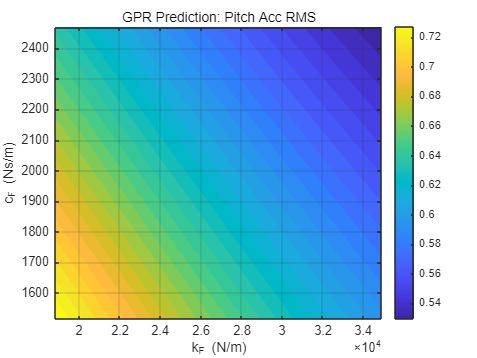

% 1. 데이터 정리
X = [ [params.k_f]' , [params.c_f]' , [params.k_r]' , [params.c_r]' ];

% 2. 출력 지표들
y_targets = {
    [params.theta_ddot_rms]',      'Pitch Acc RMS';
    [params.phi_ddot_rms]',       'Roll Acc RMS';
    [params.z_rms]',              'Heave RMS';
    [params.yaw_gain_rms]',       'Yaw Gain RMS';
    [params.phi_rms]',            'Roll Angle RMS';
    [params.y_ddot_rms]',         'Lateral Acc RMS'
};

% 3. 고정값 (mean of k_r, c_r)
k_r_mean = mean([params.k_r]);
c_r_mean = mean([params.c_r]);

% 4. 격자 생성 (k_f vs c_f)
k_f_grid = linspace(min(X(:,1)), max(X(:,1)), 50);
c_f_grid = linspace(min(X(:,2)), max(X(:,2)), 50);
[KF, CF] = meshgrid(k_f_grid, c_f_grid);
KR = k_r_mean * ones(size(KF));
CR = c_r_mean * ones(size(CF));
X_query = [KF(:), CF(:), KR(:), CR(:)];

% 5. 시각화 루프
for idx = 1:size(y_targets,1)
    y = y_targets{idx,1};
    y_name = y_targets{idx,2};

    % GPR 모델 학습
    gprM = fitrgp(X, y, 'KernelFunction', 'ardsquaredexponential', 'Standardize', true);

    % 예측
    y_pred = predict(gprM, X_query);
    y_grid = reshape(y_pred, size(KF));

    % 등고선 시각화
    figure;
    contourf(KF, CF, y_grid, 30, 'LineColor','none');
    colorbar;
    xlabel('k_F (N/m)');
    ylabel('c_F (Ns/m)');
    title(['GPR Prediction: ' y_name]);
    grid on;
end

## Section 9: Pareto 최적화 및 사용자 기반 최적 파라미터 제공

두 스코어를 기반으로 Pareto Front 구성 및 사용자 가중치 기반 최적 설계

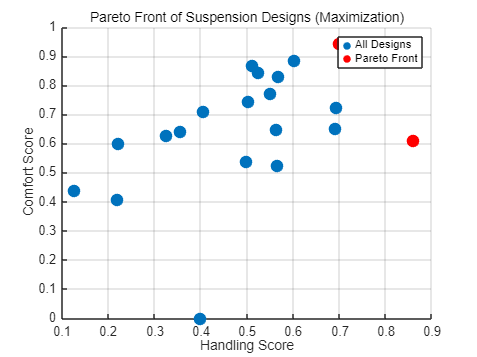

%% Step 1: 스코어 벡터 생성
score_handling = [params.handling_score]';  % 클수록 좋음
score_comfort  = [params.comfort_score]';   % 클수록 좋음

%% Step 2: Pareto Front 계산 (최대화를 위해 부호 반전)
score_matrix = [-score_handling, -score_comfort];
addpath('C:\Users\me\Desktop\연구\Surrogate Model\[Matlab] GPR Damper Optimization');
savepath;  % 다음 실행 때도 기억

pareto_flags = paretofront(score_matrix);  % 최소화 기반이므로 부호 반전 필요

%% Step 3: Pareto Front 시각화
figure;
scatter(score_handling, score_comfort, 100, 'o', 'filled'); hold on;
scatter(score_handling(pareto_flags), score_comfort(pareto_flags), ...
        100, 'r', 'filled');
xlabel('Handling Score'); ylabel('Comfort Score');
title('Pareto Front of Suspension Designs (Maximization)');
legend('All Designs', 'Pareto Front'); grid on;


%% Step 4: 사용자 가중치 기반 Total Score 계산 (Handling:Comfort = 0.7:0.3)
weight_handling = 0.7;
weight_comfort  = 0.3;
total_score = weight_handling * score_handling + weight_comfort * score_comfort;

%% Step 5: Pareto 내에서 최대 Total Score를 갖는 최적 설계 선택
pareto_idx = find(pareto_flags);
[~, best_local_idx] = max(total_score(pareto_idx));  % 최대화!
best_idx = pareto_idx(best_local_idx);

%% Step 6: 최종 추천 설계 출력
fprintf('\n== 사용자 가중치 기반 Top-1 추천 설계 (Pareto 내) ==\n');


== 사용자 가중치 기반 Top-1 추천 설계 (Pareto 내) ==


fprintf('→ Design #%d: %s\n', best_idx, params(best_idx).legend);

→ Design #4: kF=34588, cF=1576, kR=25006, cR=1593


fprintf('   Handling Score = %.4f, Comfort Score = %.4f, Total Score = %.4f\n', ...
        score_handling(best_idx), score_comfort(best_idx), total_score(best_idx));

   Handling Score = 0.8603, Comfort Score = 0.6096, Total Score = 0.7851


%% Section 9: GPR 예측 기반 Pareto 최적화 (Full Grid 탐색, 정규화 포함)

%% Section 9: GPR 예측 기반 Pareto 최적화 (Full Grid 탐색, 정규화 포함)

% Step 1: 설계 변수 범위 정의
kF_range = linspace(min(X(:,1)), max(X(:,1)), 20);  % N/m
cF_range = linspace(min(X(:,2)), max(X(:,2)), 20);  % Ns/m
kR_range = linspace(min(X(:,3)), max(X(:,3)), 20);  % N/m
cR_range = linspace(min(X(:,4)), max(X(:,4)), 20);  % Ns/m

[KF, CF, KR, CR] = ndgrid(kF_range, cF_range, kR_range, cR_range);
X_full = [KF(:), CF(:), KR(:), CR(:)];  % size: (N x 4)

% Step 2: GPR 모델 기반 예측
H_pred_raw = predict(gprModel_handling, X_full);
C_pred_raw = predict(gprModel_comfort,  X_full);

% Step 2-1: 정규화 함수 정의 및 적용
normalize = @(x) (x - min(x)) / (max(x) - min(x));
H_pred = normalize(H_pred_raw);
C_pred = normalize(C_pred_raw);

% Step 3: Pareto Front 계산 (Handling, Comfort 모두 최대화이므로 음수로 변환하여 최소화)
pareto_flags = paretofront([-H_pred, -C_pred]);

%% Step 4: 가중치 기반 Total Score 및 최적 설계 반복 탐색

w_range = 0.1:0.1:0.9;           % Handling 가중치 (Comfort는 1 - w_h)
colors = jet(length(w_range));   % 시각화를 위한 색상 정의
legend_entries = {};             % 범례용 cell array

figure; hold on; grid on;
xlabel('Handling Score (Normalized)');
ylabel('Comfort Score (Normalized)');
title('Pareto Fronts with Weighted Optimal Designs');

% Pareto Front (회색 점으로 공통 표시)
scatter(H_pred(pareto_flags), C_pred(pareto_flags), 10, [0.6 0.6 0.6], 'filled');

for i = 1:length(w_range)
    w_h = w_range(i);
    w_c = 1 - w_h;

    % Total Score 계산
    total_score = w_h * H_pred + w_c * C_pred;

    % Pareto 내에서 최고 Total Score 선택
    pareto_idx = find(pareto_flags);
    [~, best_local_idx] = max(total_score(pareto_idx));
    best_idx = pareto_idx(best_local_idx);

    % 결과 출력
    fprintf('\n== GPR 기반 Pareto 최적 설계 (Handling:Comfort = %.1f:%.1f) ==\n', w_h, w_c);
    fprintf('kF = %.1f N/m, cF = %.2f Ns/m, kR = %.1f N/m, cR = %.2f Ns/m\n', ...
            X_full(best_idx,1), X_full(best_idx,2), X_full(best_idx,3), X_full(best_idx,4));
    fprintf('Handling Score = %.4f, Comfort Score = %.4f, Total Score = %.4f\n', ...
            H_pred(best_idx), C_pred(best_idx), total_score(best_idx));

    % 최적 점 시각화 (컬러별)
    scatter(H_pred(best_idx), C_pred(best_idx), 60, colors(i,:), 'filled');
    legend_entries{end+1} = sprintf('w_h: %.1f, w_c: %.1f', w_h, w_c);
end


== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.1:0.9) ==


kF = 34587.9 N/m, cF = 2452.66 Ns/m, kR = 34605.7 N/m, cR = 2483.96 Ns/m


Handling Score = 0.6064, Comfort Score = 1.0000, Total Score = 0.9606



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.2:0.8) ==


kF = 34587.9 N/m, cF = 2452.66 Ns/m, kR = 34605.7 N/m, cR = 2483.96 Ns/m


Handling Score = 0.6064, Comfort Score = 1.0000, Total Score = 0.9213



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.3:0.7) ==


kF = 34587.9 N/m, cF = 2452.66 Ns/m, kR = 34605.7 N/m, cR = 2483.96 Ns/m


Handling Score = 0.6064, Comfort Score = 1.0000, Total Score = 0.8819



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.4:0.6) ==


kF = 34587.9 N/m, cF = 2452.66 Ns/m, kR = 34605.7 N/m, cR = 2483.96 Ns/m


Handling Score = 0.6064, Comfort Score = 1.0000, Total Score = 0.8426



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.5:0.5) ==


kF = 34587.9 N/m, cF = 1540.55 Ns/m, kR = 34605.7 N/m, cR = 1534.00 Ns/m


Handling Score = 1.0000, Comfort Score = 0.6882, Total Score = 0.8441



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.6:0.4) ==


kF = 34587.9 N/m, cF = 1540.55 Ns/m, kR = 34605.7 N/m, cR = 1534.00 Ns/m


Handling Score = 1.0000, Comfort Score = 0.6882, Total Score = 0.8753



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.7:0.3) ==


kF = 34587.9 N/m, cF = 1540.55 Ns/m, kR = 34605.7 N/m, cR = 1534.00 Ns/m


Handling Score = 1.0000, Comfort Score = 0.6882, Total Score = 0.9065



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.8:0.2) ==


kF = 34587.9 N/m, cF = 1540.55 Ns/m, kR = 34605.7 N/m, cR = 1534.00 Ns/m


Handling Score = 1.0000, Comfort Score = 0.6882, Total Score = 0.9376



== GPR 기반 Pareto 최적 설계 (Handling:Comfort = 0.9:0.1) ==


kF = 34587.9 N/m, cF = 1540.55 Ns/m, kR = 34605.7 N/m, cR = 1534.00 Ns/m


Handling Score = 1.0000, Comfort Score = 0.6882, Total Score = 0.9688


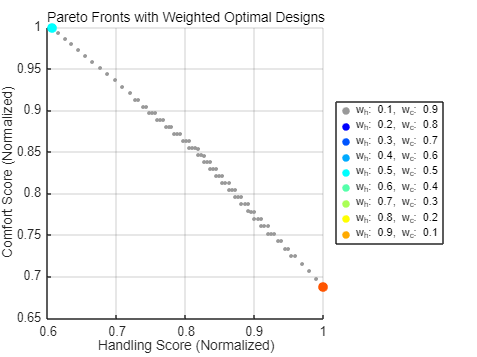


legend(legend_entries, 'Location', 'eastoutside');

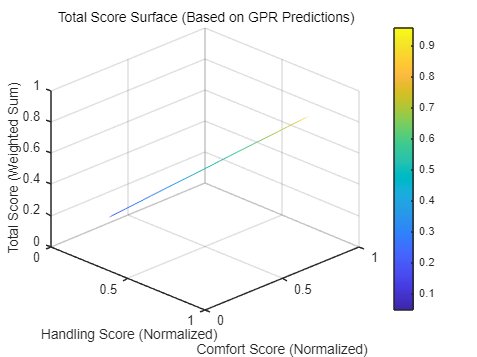


%% (Optional) Step 5: Total Score Surface 시각화 (Handling vs Comfort)

% 2D grid 생성
[H_grid, C_grid] = meshgrid(linspace(0,1,100), linspace(0,1,100));
F = scatteredInterpolant(H_pred, C_pred, total_score, 'natural', 'none');
Z_grid = F(H_grid, C_grid);  % 각 위치에서 Total Score 예측값

figure;
surf(H_grid, C_grid, Z_grid, 'EdgeColor', 'none'); 
xlabel('Handling Score (Normalized)');
ylabel('Comfort Score (Normalized)');
zlabel('Total Score (Weighted Sum)');
title('Total Score Surface (Based on GPR Predictions)');
colorbar;
view(45, 30); grid on;




% 노이즈를 추가하고 test 포인트를 넣어서 모델의 정확성을 확인한다.
% 학습데이터 범위에서 임의로 테스트포인트를 넣는다.
% 실제 센서떄의 노이즈까지 가정해서, 정확도가 얼마나 바뀌는지.  Numerical Simulation using MATLAB 관련한 ppt 한페이지를만들어야하는데 뭐가들어가야할까? 


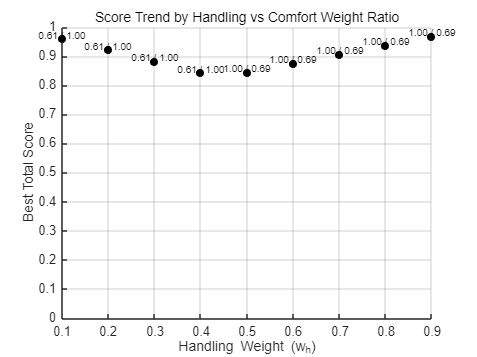

% =================== 기존 코드 (Step 1~3: Grid 생성 및 예측) ===================
kF_range = linspace(min(X(:,1)), max(X(:,1)), 20);
cF_range = linspace(min(X(:,2)), max(X(:,2)), 20);
kR_range = linspace(min(X(:,3)), max(X(:,3)), 20);
cR_range = linspace(min(X(:,4)), max(X(:,4)), 20);

[KF, CF, KR, CR] = ndgrid(kF_range, cF_range, kR_range, cR_range);
X_full = [KF(:), CF(:), KR(:), CR(:)];

H_pred_raw = predict(gprModel_handling, X_full);
C_pred_raw = predict(gprModel_comfort,  X_full);

normalize = @(x) (x - min(x)) / (max(x) - min(x));
H_pred = normalize(H_pred_raw);
C_pred = normalize(C_pred_raw);

pareto_flags = paretofront([-H_pred, -C_pred]);

% =================== 추가 기능: 다양한 가중치 시나리오 ===================
weight_list = 0.1:0.1:0.9;
score_table = [];  % [w_h, w_c, TotalScore, H_score, C_score, kF, cF, kR, cR]

figure; hold on; grid on;

for i = 1:length(weight_list)
    w_h = weight_list(i);
    w_c = 1 - w_h;

    total_score = w_h * H_pred + w_c * C_pred;

    pareto_idx = find(pareto_flags);
    [~, best_local_idx] = max(total_score(pareto_idx));
    best_idx = pareto_idx(best_local_idx);

    % 설계변수 추출
    best_design = X_full(best_idx, :);  % [kF, cF, kR, cR]

    % 결과 저장
    score_table = [score_table;
        w_h, w_c, total_score(best_idx), H_pred(best_idx), C_pred(best_idx), ...
        best_design(1), best_design(2), best_design(3), best_design(4)];

    % 플롯에 점 추가
    plot(w_h, total_score(best_idx), 'ko', 'MarkerFaceColor', 'k');
    text(w_h, total_score(best_idx)+0.01, ...
        sprintf('%.2f / %.2f', H_pred(best_idx), C_pred(best_idx)), ...
        'HorizontalAlignment', 'center', 'FontSize', 8);
end

xlabel('Handling Weight (w_h)');
ylabel('Best Total Score');
title('Score Trend by Handling vs Comfort Weight Ratio');
ylim([0 1]);


% =================== 결과 테이블 출력 ===================
result_table = array2table(score_table, ...
    'VariableNames', {'w_h', 'w_c', 'TotalScore', ...
                      'HandlingScore', 'ComfortScore', ...
                      'kF', 'cF', 'kR', 'cR'});

disp('== Summary of Best Designs for Each Weight Scenario ==');

== Summary of Best Designs for Each Weight Scenario ==


disp(result_table);

    w_h    w_c    TotalScore    HandlingScore    ComfortScore     kF        cF       kR       cR 
    ___    ___    __________    _____________    ____________    _____    ______    _____    ____

    0.1    0.9     0.96064         0.60638               1       34588    2452.7    34606    2484
    0.2    0.8     0.92128         0.60638               1       34588    2452.7    34606    2484
    0.3    0.7     0.88191         0.60638               1       34588    2452.7    34606    2484
    0.4    0.6     0.84255         0.60638               1       34588    2452.7    34606    2484
    0.5    0.5     0.84411               1         0.68821       34588    1540.6    34606    1534
    0.6    0.4     0.87529               1         0.68821       34588    1540.6    34606    1534
    0.7    0.3     0.90646               1         0.68821       34588    1540.6    34606    1534
    0.8    0.2     0.93764               1         0.68821       34588    1540.6    34606    1534
    0.9    0.1     

%% Baseline 설계 변수 계산 (범위 중간값 사용)
kF_mid = mean([min(X(:,1)), max(X(:,1))]);
cF_mid = mean([min(X(:,2)), max(X(:,2))]);
kR_mid = mean([min(X(:,3)), max(X(:,3))]);
cR_mid = mean([min(X(:,4)), max(X(:,4))]);

X_baseline = [kF_mid, cF_mid, kR_mid, cR_mid];

%% GPR 기반 예측
H_baseline = predict(gprModel_handling, X_baseline);
C_baseline = predict(gprModel_comfort,  X_baseline);

% 정규화
H_baseline_norm = (H_baseline - min(H_pred_raw)) / (max(H_pred_raw) - min(H_pred_raw));
C_baseline_norm = (C_baseline - min(C_pred_raw)) / (max(C_pred_raw) - min(C_pred_raw));

% 클리핑
H_baseline_norm = max(0, min(1, H_baseline_norm));
C_baseline_norm = max(0, min(1, C_baseline_norm));

% Total Score 계산 (w_h = 0.8, w_c = 0.2)
w_h = 0.8; w_c = 0.2;
Total_baseline = w_h * H_baseline_norm + w_c * C_baseline_norm;

%% 기존 score_table에서 w_h=0.8인 행 찾기
row_target = result_table.w_h == 0.8;

%% 비교 출력
fprintf('\n== 비교: Baseline vs Best (w_h=0.8, w_c=0.2) ==\n');


== 비교: Baseline vs Best (w_h=0.8, w_c=0.2) ==


fprintf('%-20s | %-12s | %-12s\n', 'Metric', 'Baseline', 'Best@w=0.8');

Metric               | Baseline     | Best@w=0.8  


fprintf('----------------------|--------------|--------------\n');

----------------------|--------------|--------------


fprintf('%-20s | %-12.4f | %-12.4f\n', 'Handling Score', H_baseline_norm, result_table.HandlingScore(row_target));

Handling Score       | 0.5518       | 1.0000      


fprintf('%-20s | %-12.4f | %-12.4f\n', 'Comfort Score',  C_baseline_norm, result_table.ComfortScore(row_target));

Comfort Score        | 0.6543       | 0.6882      


fprintf('%-20s | %-12.4f | %-12.4f\n', 'Total Score',    Total_baseline, result_table.TotalScore(row_target));

Total Score          | 0.5723       | 0.9376      


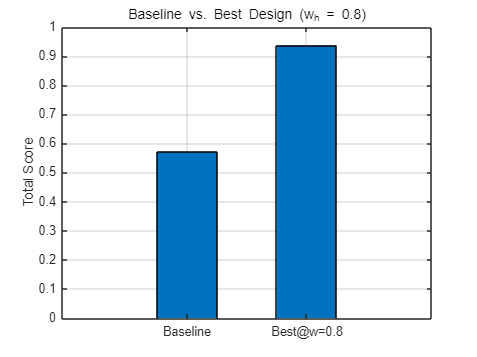


%% (선택) 시각화 비교
figure;
bar([1,2], [Total_baseline, result_table.TotalScore(row_target)], 0.5);
set(gca, 'XTickLabel', {'Baseline', 'Best@w=0.8'});
ylabel('Total Score');
title('Baseline vs. Best Design (w_h = 0.8)');
grid on;

%% GPR Surrogate Model Validation using Random Test Points
n_test = 20;

% 테스트 포인트 생성 (LHS 사용하여 설계 변수 범위 내에서 랜덤 생성)
lhs_test = lhsdesign(n_test, 4);
X_test = zeros(n_test, 4);
for i = 1:4
    X_test(:,i) = min(X(:,i)) + (max(X(:,i)) - min(X(:,i))) * lhs_test(:,i);
end

% GPR 예측값 계산
H_pred_test = predict(gprModel_handling, X_test);
C_pred_test = predict(gprModel_comfort,  X_test);

% 실제 시뮬레이션 수행
H_true = zeros(n_test, 1);
C_true = zeros(n_test, 1);

for i = 1:n_test
    pf.k_f = X_test(i,1);
    pf.c_f = X_test(i,2);
    pf.k_r = X_test(i,3);
    pf.c_r = X_test(i,4);

    % 시뮬레이션 실행
    [theta_ddot_rms, phi_ddot_rms, z_rms] = runPitchRollHeave(pf);
    [yaw_gain_rms, phi_rms, y_ddot_rms] = runHandlingMetrics(pf);

    % 디버깅용 출력
    fprintf('\n[Test %d] RMS Outputs:\n', i);
    fprintf('theta_ddot_rms: %.4f\n', theta_ddot_rms);
    fprintf('phi_ddot_rms  : %.4f\n', phi_ddot_rms);
    fprintf('z_rms         : %.4f\n', z_rms);
    fprintf('yaw_gain_rms  : %.4f\n', yaw_gain_rms);
    fprintf('phi_rms       : %.4f\n', phi_rms);
    fprintf('y_ddot_rms    : %.4f\n', y_ddot_rms);

    % 정규화 후 Handling & Comfort 점수 계산
    yaw_norm  = (yaw_gain_rms - min(yaw_gain_all)) / (max(yaw_gain_all) - min(yaw_gain_all));
    roll_norm = (phi_rms       - min(roll_angle_all)) / (max(roll_angle_all) - min(roll_angle_all));
    lat_norm  = (y_ddot_rms    - min(lat_acc_all)) / (max(lat_acc_all) - min(lat_acc_all));

    pitch_norm = (theta_ddot_rms - min(pitch_acc_all)) / (max(pitch_acc_all) - min(pitch_acc_all));
    roll_acc_norm = (phi_ddot_rms - min(roll_acc_all)) / (max(roll_acc_all) - min(roll_acc_all));
    heave_norm    = (z_rms - min(heave_all)) / (max(heave_all) - min(heave_all));

    % 클리핑 (0~1 범위 보장)
    yaw_norm  = max(0, min(1, yaw_norm));
    roll_norm = max(0, min(1, roll_norm));
    lat_norm  = max(0, min(1, lat_norm));
    pitch_norm = max(0, min(1, pitch_norm));
    roll_acc_norm = max(0, min(1, roll_acc_norm));
    heave_norm = max(0, min(1, heave_norm));

    % Score 계산
    H_true(i) = 0.4 * yaw_norm + 0.35 * (1 - roll_norm) + 0.25 * (1 - lat_norm);
    C_true(i) = 0.3 * (1 - pitch_norm) + 0.25 * (1 - roll_acc_norm) + 0.45 * (1 - heave_norm);
end


[Test 1] RMS Outputs:


theta_ddot_rms: 47.2145


phi_ddot_rms  : 77.3651


z_rms         : 0.0075


yaw_gain_rms  : 0.7015


phi_rms       : 0.3893


y_ddot_rms    : 0.0047



[Test 2] RMS Outputs:


theta_ddot_rms: 47.1920


phi_ddot_rms  : 77.3551


z_rms         : 0.0067


yaw_gain_rms  : 0.6089


phi_rms       : 0.3470


y_ddot_rms    : 0.0042



[Test 3] RMS Outputs:


theta_ddot_rms: 47.2244


phi_ddot_rms  : 77.3696


z_rms         : 0.0079


yaw_gain_rms  : 0.5224


phi_rms       : 0.4106


y_ddot_rms    : 0.0049



[Test 4] RMS Outputs:


theta_ddot_rms: 47.2097


phi_ddot_rms  : 77.3662


z_rms         : 0.0076


yaw_gain_rms  : 0.5606


phi_rms       : 0.3952


y_ddot_rms    : 0.0047



[Test 5] RMS Outputs:


theta_ddot_rms: 47.1937


phi_ddot_rms  : 77.3551


z_rms         : 0.0067


yaw_gain_rms  : 0.5235


phi_rms       : 0.3474


y_ddot_rms    : 0.0042



[Test 6] RMS Outputs:


theta_ddot_rms: 47.2226


phi_ddot_rms  : 77.3771


z_rms         : 0.0085


yaw_gain_rms  : 0.4754


phi_rms       : 0.4443


y_ddot_rms    : 0.0052



[Test 7] RMS Outputs:


theta_ddot_rms: 47.2635


phi_ddot_rms  : 77.3965


z_rms         : 0.0102


yaw_gain_rms  : 0.5105


phi_rms       : 0.5288


y_ddot_rms    : 0.0062



[Test 8] RMS Outputs:


theta_ddot_rms: 47.1883


phi_ddot_rms  : 77.3528


z_rms         : 0.0065


yaw_gain_rms  : 0.4832


phi_rms       : 0.3383


y_ddot_rms    : 0.0040



[Test 9] RMS Outputs:


theta_ddot_rms: 47.2017


phi_ddot_rms  : 77.3603


z_rms         : 0.0071


yaw_gain_rms  : 0.5163


phi_rms       : 0.3699


y_ddot_rms    : 0.0044



[Test 10] RMS Outputs:


theta_ddot_rms: 47.2358


phi_ddot_rms  : 77.3781


z_rms         : 0.0086


yaw_gain_rms  : 0.5776


phi_rms       : 0.4467


y_ddot_rms    : 0.0053



[Test 11] RMS Outputs:


theta_ddot_rms: 47.2331


phi_ddot_rms  : 77.3774


z_rms         : 0.0085


yaw_gain_rms  : 0.6406


phi_rms       : 0.4427


y_ddot_rms    : 0.0053



[Test 12] RMS Outputs:


theta_ddot_rms: 47.2030


phi_ddot_rms  : 77.3634


z_rms         : 0.0074


yaw_gain_rms  : 0.5427


phi_rms       : 0.3833


y_ddot_rms    : 0.0046



[Test 13] RMS Outputs:


theta_ddot_rms: 47.1878


phi_ddot_rms  : 77.3505


z_rms         : 0.0063


yaw_gain_rms  : 0.5757


phi_rms       : 0.3273


y_ddot_rms    : 0.0039



[Test 14] RMS Outputs:


theta_ddot_rms: 47.2492


phi_ddot_rms  : 77.3845


z_rms         : 0.0091


yaw_gain_rms  : 0.6403


phi_rms       : 0.4738


y_ddot_rms    : 0.0057



[Test 15] RMS Outputs:


theta_ddot_rms: 47.1974


phi_ddot_rms  : 77.3560


z_rms         : 0.0068


yaw_gain_rms  : 0.5117


phi_rms       : 0.3517


y_ddot_rms    : 0.0042



[Test 16] RMS Outputs:


theta_ddot_rms: 47.2179


phi_ddot_rms  : 77.3666


z_rms         : 0.0076


yaw_gain_rms  : 0.4884


phi_rms       : 0.3979


y_ddot_rms    : 0.0047



[Test 17] RMS Outputs:


theta_ddot_rms: 47.2031


phi_ddot_rms  : 77.3578


z_rms         : 0.0069


yaw_gain_rms  : 0.5437


phi_rms       : 0.3591


y_ddot_rms    : 0.0043



[Test 18] RMS Outputs:


theta_ddot_rms: 47.2374


phi_ddot_rms  : 77.3829


z_rms         : 0.0090


yaw_gain_rms  : 0.5343


phi_rms       : 0.4683


y_ddot_rms    : 0.0056



[Test 19] RMS Outputs:


theta_ddot_rms: 47.2531


phi_ddot_rms  : 77.3914


z_rms         : 0.0097


yaw_gain_rms  : 0.6250


phi_rms       : 0.5038


y_ddot_rms    : 0.0060



[Test 20] RMS Outputs:


theta_ddot_rms: 47.2260


phi_ddot_rms  : 77.3783


z_rms         : 0.0086


yaw_gain_rms  : 0.4693


phi_rms       : 0.4495


y_ddot_rms    : 0.0053



% RMSE 계산
rmse_handling = sqrt(mean((H_pred_test - H_true).^2));
rmse_comfort  = sqrt(mean((C_pred_test - C_true).^2));

fprintf('\n== GPR Surrogate Model Validation ==\n');


== GPR Surrogate Model Validation ==


fprintf('Handling Score RMSE = %.4f\n', rmse_handling);

Handling Score RMSE = 0.0449


fprintf('Comfort Score  RMSE = %.4f\n', rmse_comfort);

Comfort Score  RMSE = 0.3972



% 결과 테이블 출력
disp(table(H_pred_test, H_true, C_pred_test, C_true, ...
    'VariableNames', {'H_pred', 'H_true', 'C_pred', 'C_true'}));

    H_pred      H_true     C_pred      C_true 
    _______    ________    _______    ________

    0.76423     0.74723    0.49147     0.30635
    0.75771     0.71259    0.74891     0.39489
     0.4378     0.38575    0.68813     0.26178
    0.54384     0.49268    0.66541     0.29406
    0.60748     0.56625    0.83958     0.39414
    0.24703     0.21604    0.70706     0.19118
    0.12094    0.077874    0.33133    0.014243
    0.55746     0.52531    0.97602     0.41306
    0.53535     0.49031    0.80374     0.34703
    0.42799     0.37405    0.45385     0.18614
    0.53549     0.49121    0.38397     0.19449
    0.54095      0.4973    0.75625     0.31886
    0.74948     0.71281    0.84854     0.43618
    0.45041     0.40267      0.289     0.12946
    0.57862     0.53526    0.89369     0.38506
     0.4133     0.36405    0.77298     0.28822
    0.61284     0.56802    0.81802     0.36964
    0.30028     0.24098    0.48216     0.14083
    0.35749     0.29488    0.22861    0.066496
    0.23123 